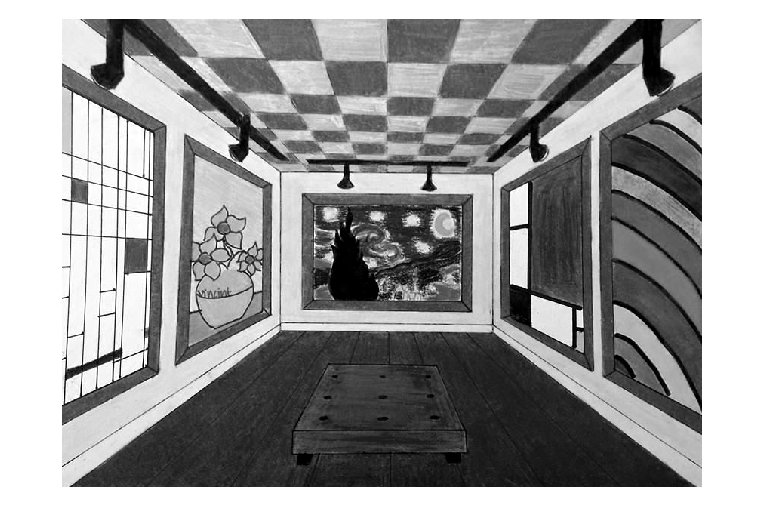

% TIP basic algorithmus
% Vanishing points analysis
% Version: 1.0
% Last change: 24.06.2024
% Author: Cheng chen

clc;
clearvars;

%% Image prepration
% import image, converting it to grayscale and enhacing the contrast 
% to better delineate edges and lines

%------------------------------- TODO --------------------------------------
% choose different image input to find the best funtion parameters

% easy
img = im2double(imread('simple-room.png'));
%img = im2double(imread('oil-painting.png'));

% middel
%img = im2double(imread('shopping-mall.png'));
%img = im2double(imread('uhren-turm.jpg'));

% difficult
%img = im2double(imread('metro-station.png'));
%img = im2double(imread('sagrada_familia.png'));
%------------------------------- TODO end -----------------------------------

gray = rgb2gray(img);
gray = imadjust(gray);
figure ,imshow(gray);

% 1.Background reconstruction
% 1.1 Perspective analysis

%% Edge detection using sobel
% using Canny detector to identify edges, which will used for recgnize
% perspective lines

%------------------------------- TODO --------------------------------------
% test different threshold and method('soble','prewitt','roberts'...) for
% different image input
[edges, threshold] = edge(gray, 'canny');
disp(threshold);

    0.0375    0.0938



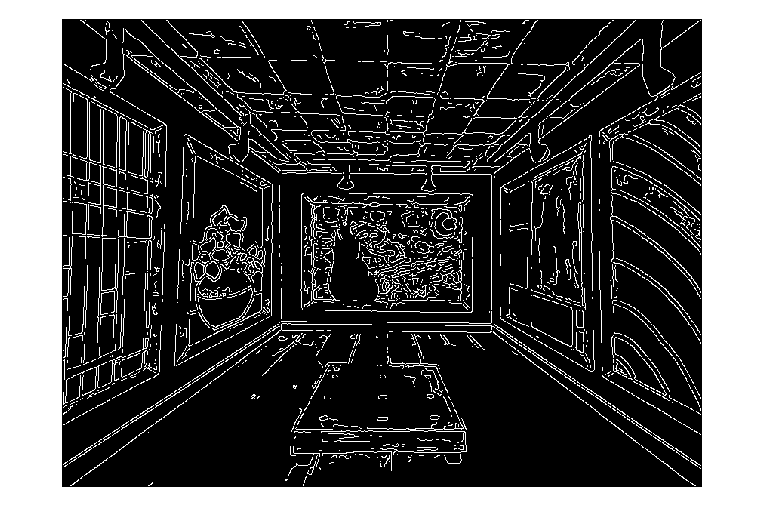

%threshold = 0.07;
%edges = edge(gray, 'sobel', threshold);
%------------------------------- TODO end -----------------------------------

figure, imshow(edges);

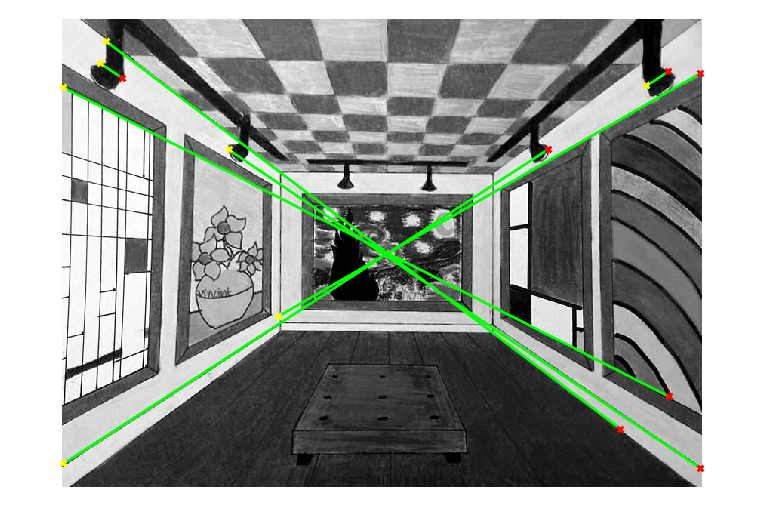

%% Lines detection using Hough Transform
% apply the Hough Transform to detect lines from the edge, which 
% will be used for subsequent vanishing point analysis.

[H, theta, rho] = hough(edges);

%------------------------------- TODO --------------------------------------
% test different value of 'numpeaks', 'FillGap' and 'Minlength' for
% different image input
peaks = houghpeaks(H, 5, 'Threshold', ceil(0.3*max(H(:)))); % find peaks
lines = houghlines(edges, theta, rho, peaks, 'FillGap', 100, 'MinLength',20); % find lines
%------------------------------- TODO end -----------------------------------

% Display detected lines
figure, imshow(gray), hold on;
max_len = 0;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');

    % Plot beginnings and ends of lines
    plot(xy(1,1), xy(1,2), 'x', 'LineWidth', 2, 'Color', 'yellow');
    plot(xy(2,1), xy(2,2), 'x', 'LineWidth', 2, 'Color', 'red');
end
hold off;

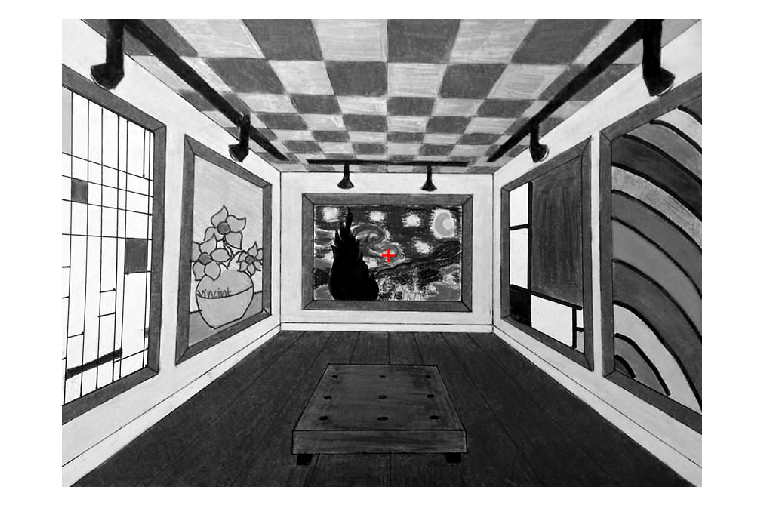

%% Vanishing point analysis
% calculate intersections from the lines obtained from the Hough Transform,
% these intersections are potential vanishing points

% Simple clustering of vanishing points
points = [];
for i = 1:length(lines)
    for j = i+1:length(lines)
        [x, y] = intersection(lines(i), lines(j));
        if ~isnan(x) && ~isnan(y)
            points = [points; x, y];
        end
    end
end

% Clustering
if ~isempty(points)
    vanish_point = mean(points, 1);
    figure, imshow(gray), hold on;
    plot(vanish_point(1), vanish_point(2), 'r+', 'MarkerSize', 10, 'LineWidth', 2);
    hold off;
end


function [x, y] = intersection(line1, line2)
% calculating the intersection of 2 lines

    % Extracting parameters from the lines
    theta1 = line1.theta * pi / 180; % Convert degrees to radians
    rho1 = line1.rho;
    theta2 = line2.theta * pi / 180;
    rho2 = line2.rho;
    
    % Constructing matrix equation Ax = b
    A = [cos(theta1) sin(theta1); cos(theta2) sin(theta2)];
    b = [rho1; rho2];
    
    % Solve the linear equations using matrix left division
    if rank(A) == 2 % Only solve if the matrix is full rank
        x = A \ b;
        y = x(2);
        x = x(1);
    else
        x = NaN; % No solution
        y = NaN;
    end
end